# DTFS for Pulse Train

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Consider a discrete-time pulse train one period of which is defined in the interval $n=-L,\ldots,N-L-1$ as


$$\tilde{x}[n] = \left\{\begin{array}{c l} 
1,\; & -L\le n\le L \\
0,\; & L<n<N-L
\end{array}\right.$$


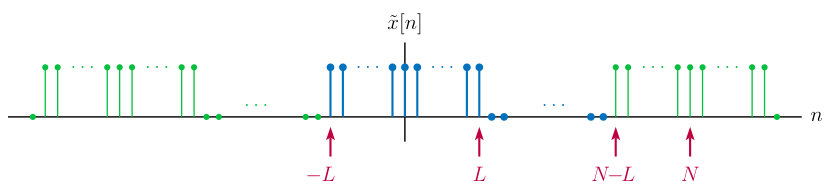

For details, see Section 3.2.2 of 

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach *

by O. Alkin

N = 40;  % Period length
L = 3;  % Parameter 'L'
Omega0 = 2*pi/N;   % Vector of angular frequencies
k = [0:N-1];       % Coefficient indices

Compute DTFS coefficients for the signal $\tilde{x}[n]$.  See Example 3.5 and Eqn. (3.22) in the text.

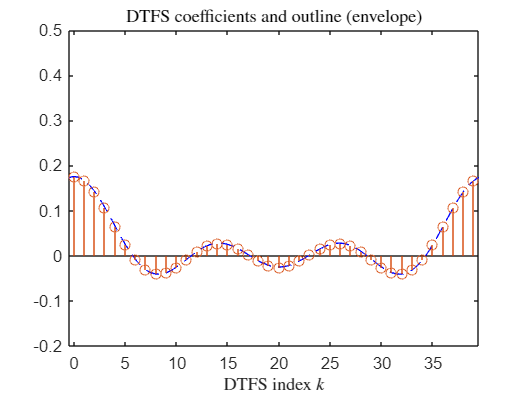

% Compute DTFS coefficients
% Use 'eps' to avoid division by zero
c = sin(Omega0/2*(k+eps)*(2*L+1))./sin(Omega0/2*(k+eps))/N;
% Compute the envelope (by allowing non-integer values of 
% the index)
k2 = [-0.5:0.01:N-1+0.5];
% Compute the envelope
env = sin(Omega0/2*(k2+eps)*(2*L+1))./sin(Omega0/2*(k2+eps))/N;
plot(k2,env,'b--');
set(0,'defaultTextInterpreter','latex');
axis([-0.5,N-0.5,-0.2,0.5])
hold on;
stem(k,c);
hold off;
xlabel('DTFS index $k$');
title('DTFS coefficients and outline (envelope)');

set(0,'defaultTextInterpreter','tex');